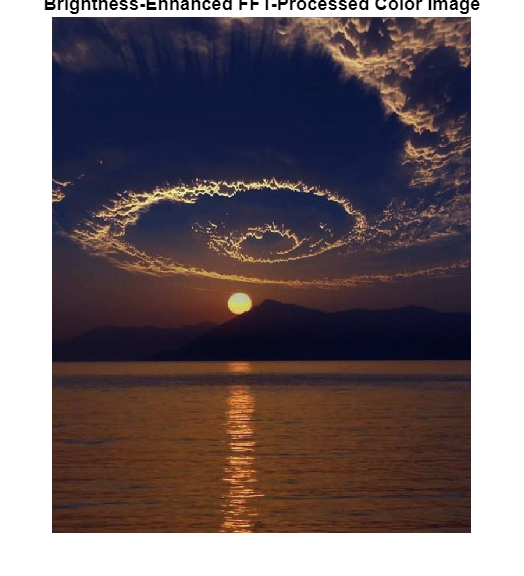

% Read the input image in color
img = imread('C:\Users\priya\Downloads\75a57113f4e40776d3a66424f0c85eb268e2dcd1.jpeg');

% Increase brightness by a factor
brightness_factor = 1.2; % Adjust as needed
img = imadjust(img, [], [], brightness_factor);

% Convert to double for FFT processing
img = im2double(img);

% Extract RGB channels
R = img(:,:,1);
G = img(:,:,2);
B = img(:,:,3);

% Apply FFT to each channel
fft_R = fft2(R);
fft_G = fft2(G);
fft_B = fft2(B);

% Shift zero frequency to center for visualization
fft_R_shifted = fftshift(log(abs(fft_R) + 1));
fft_G_shifted = fftshift(log(abs(fft_G) + 1));
fft_B_shifted = fftshift(log(abs(fft_B) + 1));

% Remove low-frequency components (enhance details)
threshold = 20; % Lowered to retain more details
fft_R(abs(fft_R) < threshold) = 0;
fft_G(abs(fft_G) < threshold) = 0;
fft_B(abs(fft_B) < threshold) = 0;

% Apply inverse FFT to get the enhanced image
filtered_R = real(ifft2(fft_R));
filtered_G = real(ifft2(fft_G));
filtered_B = real(ifft2(fft_B));

% Normalize intensity to prevent fading
filtered_R = mat2gray(filtered_R);
filtered_G = mat2gray(filtered_G);
filtered_B = mat2gray(filtered_B);

% Reconstruct the color image
filtered_img = cat(3, filtered_R, filtered_G, filtered_B);

% Save the enhanced color image
imwrite(filtered_img, 'C:\Users\priya\Downloads\filtered_image_color.jpg');

% Display the processed image
imshow(filtered_img); title('Brightness-Enhanced FFT-Processed Color Image');